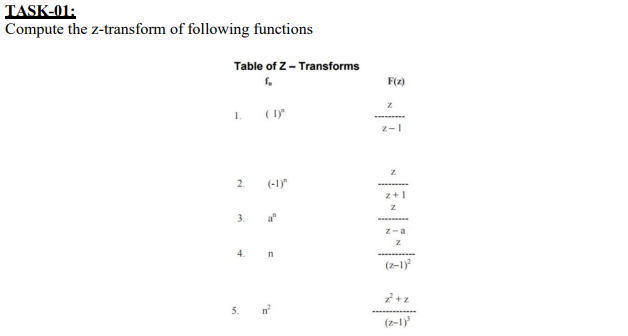

% Define symbolic variable
syms n z;

% Define functions
fn1 = 1^n;
fn2 = (-1)^n;
a = sym('a'); % Define symbolic variable 'a'
fn3 = a^n;
fn4 = n;
fn5 = n^2;

% Compute Z-transforms
F1 = ztrans(fn1, n, z);
F2 = ztrans(fn2, n, z);
F3 = ztrans(fn3, n, z);
F4 = ztrans(fn4, n, z);
F5 = ztrans(fn5, n, z);

% Display Z-transform results
disp('Z-transform of f1(n) = 1^n:')

Z-transform of f1(n) = 1^n:


disp(F1)

$$\frac{z}{z-1}$$


disp('Z-transform of f2(n) = (-1)^n:')

Z-transform of f2(n) = (-1)^n:


disp(F2)

$$\frac{z}{z+1}$$


disp('Z-transform of f3(n) = a^n:')

Z-transform of f3(n) = a^n:


disp(F3)

$$-\frac{z}{a-z}$$


disp('Z-transform of f4(n) = n:')

Z-transform of f4(n) = n:


disp(F4)

$$\frac{z}{{\left(z-1\right)}^{2}}$$


disp('Z-transform of f5(n) = n^2:')

Z-transform of f5(n) = n^2:


disp(F5)

$$\frac{z\,\left(z+1\right)}{{\left(z-1\right)}^{3}}$$

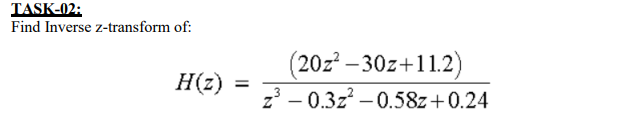

clc;
clear all;

% Define symbolic variable
syms z;

% Define transfer function H1
H1 = ((20*z^2) - (30*z) + 11.2) / (z^3 - 0.3*z^2 - 0.58*z + 0.24);

% Find inverse z-transform for H1
inv_H1 = iztrans(H1, z);

% Display the inverse z-transform result for H1
disp('Inverse z-transform of H1(z):');

Inverse z-transform of H1(z):


disp(inv_H1);

$$\frac{100\,{\left(\frac{3}{5}\right)}^{z}}{21}-\frac{240\,{\left(\frac{1}{2}\right)}^{z}}{13}-\frac{3000\,{\left(-\frac{4}{5}\right)}^{z}}{91}+\frac{140\,\delta_{z,0}}{3}$$

% Define transfer function H2
H2 = z^2 / ((z - 1/2)*(z - 1/4));

% Find inverse z-transform for H2
inv_H2 = iztrans(H2, z);

% Display the inverse z-transform result for H2
disp('Inverse z-transform of H2(z):');

Inverse z-transform of H2(z):


disp(inv_H2);

$$2\,{\left(\frac{1}{2}\right)}^{z}-{\left(\frac{1}{4}\right)}^{z}$$

% Define transfer function H3
H3 = (20*(z - 0.8)*(z - 0.7)) / ((z - 0.6)*(z + 0.8)*(z - 0.5));

% Find inverse z-transform for H3
inv_H3 = iztrans(H3, z);

% Display the inverse z-transform result for H3
disp('Inverse z-transform of H3(z):');

Inverse z-transform of H3(z):


disp(inv_H3);

$$\frac{100\,{\left(\frac{3}{5}\right)}^{z}}{21}-\frac{240\,{\left(\frac{1}{2}\right)}^{z}}{13}-\frac{3000\,{\left(-\frac{4}{5}\right)}^{z}}{91}+\frac{140\,\delta_{z,0}}{3}$$

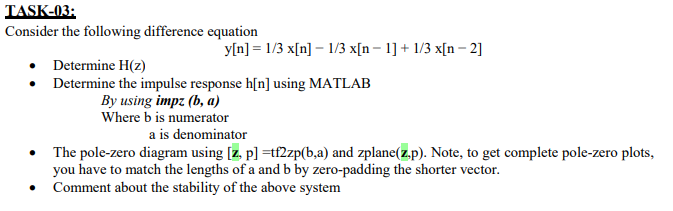

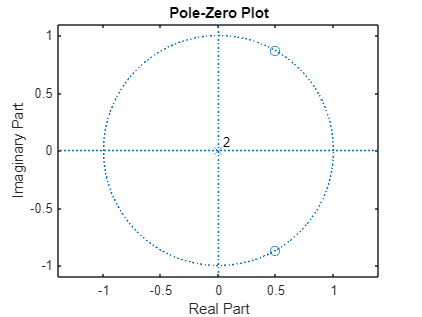

% Define the coefficients of the difference equation
b = [1/3, -1/3, 1/3];
a = [1, 0, 0]; % Denominator coefficients

% Determine H(z) from the difference equation coefficients
Hz = tf(b, a, 1); % Create transfer function

% Determine the impulse response h[n] using MATLAB
h = impz(b, a); % Get impulse response

% Zero-pad the shorter vector to match lengths
if length(b) < length(a)
    b = [b, zeros(1, length(a) - length(b))];
elseif length(a) < length(b)
    a = [a, zeros(1, length(b) - length(a))];
end

% Get the pole-zero diagram
[z, p] = tf2zp(b, a); % Get zeros and poles
figure;
zplane(z, p); % Plot pole-zero diagram


% Comment about the stability of the system
if all(abs(p) < 1) % Check if all poles are inside the unit circle
    disp('The system is stable.');
else
    disp('The system is unstable.');
end

The system is stable.


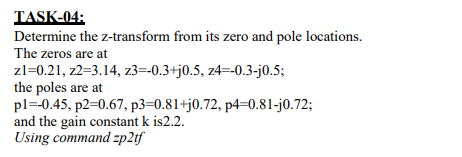

% Define the zero and pole locations as column vectors
zeros = [0.21; 3.14; -0.3+0.5i; -0.3-0.5i];
poles = [-0.45; 0.67; 0.81+0.72i; 0.81-0.72i];
k = 2.2; % Gain constant

% Convert zero-pole-gain representation to transfer function
[num, den] = zp2tf(zeros, poles, k);

% Display the transfer function
disp('The transfer function coefficients are:');

The transfer function coefficients are:


disp(['Numerator: ', num2str(num)]);

Numerator: 2.2       -6.05     -2.2233     -1.6354     0.49323


disp(['Denominator: ', num2str(den)]);

Denominator: 1       -1.84      1.2294     0.23004    -0.35411
